clear all; close all


legend_names = {'Load';'Motor'}

legend_names = 2×1 cell array
    {'Load' }
    {'Motor'}


%load side frf 
load("coherence_loadside.mat")
%removing useless data 
u = measurement(:,1)

u =     0.3036
   -0.4533
    0.4396
    0.2340
   -0.2305
    0.4659
   -0.0948
   -0.0473
    0.6246
    0.3927


d = measurement(:,2)

d =     0.2319
   -0.5249
    0.3680
    0.1623
   -0.3021
    0.3943
   -0.1665
   -0.1189
    0.5530
    0.3211


y_l = measurement(:,3)

y_l =     0.7163
    0.7163
    0.7163
    0.7163
    0.7163
    0.7163
    0.7163
    0.7163
    0.7163
    0.7163


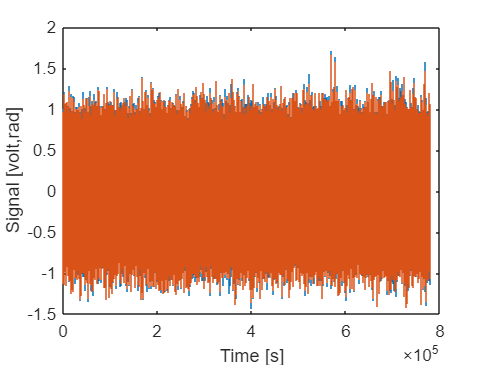


%removing useless data 
N_trash = 20e3; 
u = u(N_trash:end);
d = d(N_trash:end);
d_l = d;
y_l  = y_l(N_trash:end);

% Plot the measurement
figure(); clf();
stairs(u); hold on; stairs(d);
xlabel('Time [s]'); ylabel('Signal [volt,rad]');
hold off


%data analysis
fs = 4000 %[Hz]

fs = 4000

stepsize = 1/fs %[s]

stepsize = 2.5000e-04

max_freq = log10(fs/2) 

max_freq = 3.3010

%t_end = N_samples/fs


%window settings
min_freq = 0.1; %[Hz/s] lowest desired sampling frequency
windowsize = 1/min_freq; %[s] window size in seconds

nfft = round(windowsize/stepsize); %window size in data points 
n_overlap = round(nfft/4);

%Tf estimate
[S, F] = tfestimate(d,u,hann(nfft),n_overlap,nfft,fs); %cross spectral power density

k = 0.1

k = 0.1000

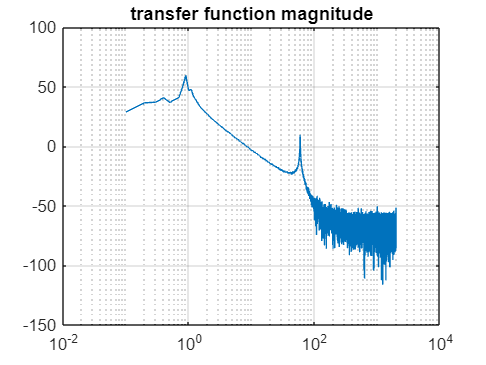

L = (1/k)*(1./S - 1);
figure()
semilogx(F,mag2db(abs(L)))
title('transfer function magnitude')
grid on; hold off

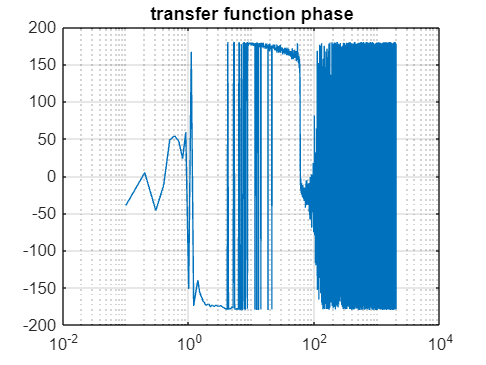


figure()
semilogx(F,angle(L)/pi*180)
title('transfer function phase')
grid on; hold off



X1 = F

X1 = 1.0e+03 *

         0
    0.0001
    0.0002
    0.0003
    0.0004
    0.0005
    0.0006
    0.0007
    0.0008
    0.0009


Y1 = mag2db(abs(L))

Y1 =    51.8514
   28.7049
   36.3943
   36.9203
   40.6765
   36.6966
   39.1103
   40.7935
   49.8129
   59.3846


Y2 = angle(L)/pi*180

Y2 =          0
  -39.5491
    4.4911
  -46.2752
  -12.4100
   48.5450
   53.9637
   46.1762
   23.2859
   58.7795


%motor side frf 
load("coherence_motorside.mat")
clear u d 
u = measurement(:,1)

u =    -0.3784
   -0.0549
    0.2952
   -0.0404
   -0.1534
    0.1658
    0.1784
   -0.0412
    0.4342
    0.0831


d = measurement(:,2)

d =    -0.2665
    0.0569
    0.4071
    0.0714
   -0.0415
    0.2823
    0.2949
    0.0757
    0.5510
    0.2002


y_m  = measurement(:,3)

y_m =     1.1184
    1.1184
    1.1184
    1.1184
    1.1184
    1.1655
    1.1655
    1.1687
    1.1687
    1.1718


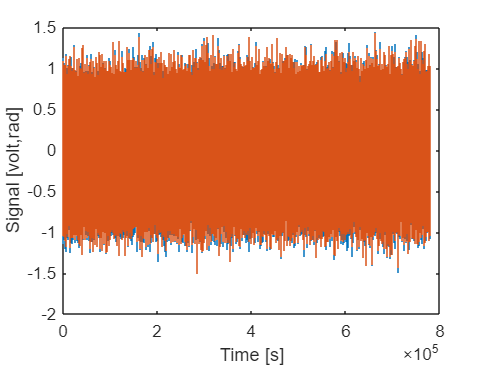

%removing useless data 
N_trash = 20e3; 
u = u(N_trash:end);
d = d(N_trash:end);
d_m = d;
y_m  = y_m(N_trash:end);
% Plot the measurement
figure(); clf();
stairs(u); hold on; stairs(d);
xlabel('Time [s]'); ylabel('Signal [volt,rad]');
hold off


%data analysis
fs = 4000 %[Hz]

fs = 4000

stepsize = 1/fs %[s]

stepsize = 2.5000e-04

max_freq = log10(fs/2) 

max_freq = 3.3010

%t_end = N_samples/fs


%window settings
min_freq = 0.1; %[Hz/s] lowest desired sampling frequency
windowsize = 1/min_freq; %[s] window size in seconds

nfft = round(windowsize/stepsize); %window size in data points 
n_overlap = round(nfft/4);

%Tf estimate
[S, F] = tfestimate(d,u,hann(nfft),n_overlap,nfft,fs); %cross spectral power density

k = 0.1

k = 0.1000

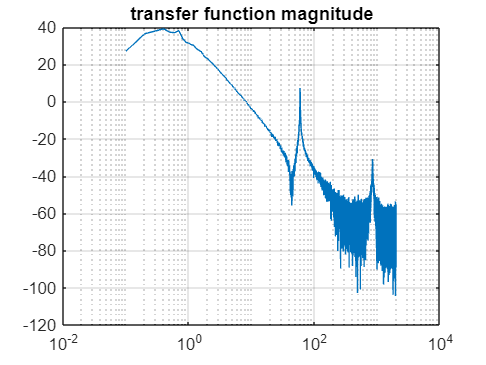

L = (1/k)*(1./S - 1);
figure()
semilogx(F,mag2db(abs(L)))
title('transfer function magnitude')
grid on; hold off

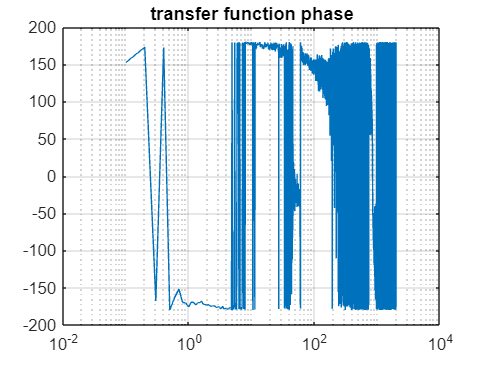


figure()
semilogx(F,angle(L)/pi*180)
title('transfer function phase')
grid on; hold off

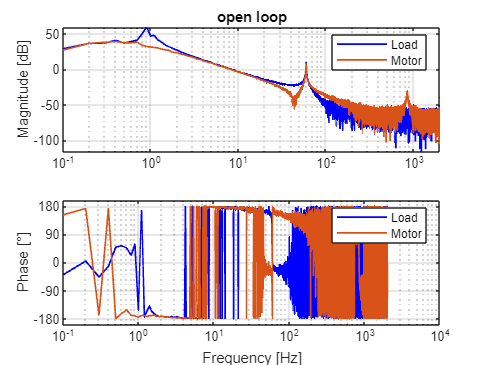

    %CREATEFIGURE(X1, Y1, Y2)
    %  X1:  vector of semilogx x data
    %  Y1:  vector of semilogx y data
    %  Y2:  vector of semilogx y data
    
    %  Auto-generated by MATLAB on 18-Apr-2024 11:36:22
    
    % Create figure
    figure1 = figure('Name','Plant frequency response');
    
    % Create axes
    axes1 = axes('Parent',figure1,...
        'Position',[0.13 0.583837209302326 0.775 0.341162790697675]);
    hold(axes1,'on');
    
    % Create semilogx
    semilogx(X1,Y1,'Parent',axes1,'LineWidth',1,'Color',[0 0 1]);
    semilogx(F,mag2db(abs(L)),'Parent',axes1,'LineWidth',1,'Color',	"#D95319")

    % Create ylabel
    ylabel('Magnitude [dB]');
    
    legend(legend_names)
    % Create title
    title('open loop');
    
    % Uncomment the following line to preserve the X-limits of the axes
    % xlim(axes1,[0.1 2000]);
    % Uncomment the following line to preserve the Y-limits of the axes
    % ylim(axes1,[-147.682410264259 47.5123737254321]);
    box(axes1,'on');
    grid(axes1,'on');
    hold(axes1,'off');
    % Set the remaining axes properties
    set(axes1,'XLimitMethod','tight','XMinorTick','on','XScale','log',...
        'YLimitMethod','tight','ZLimitMethod','tight');
    % Create axes
    axes2 = axes('Parent',figure1,...
        'Position',[0.13 0.11 0.775 0.341162790697674]);
    hold(axes2,'on');
    
    % Create semilogx
    semilogx(X1,Y2,'Parent',axes2,'LineWidth',1,'Color',[0 0 1]);
    semilogx(F,angle(L)/pi*180,'Parent',axes2,'LineWidth',1,'Color',	"#D95319")
    % Create ylabel
    ylabel('Phase [°]');
    legend(legend_names)

    % Create xlabel
    xlabel('Frequency [Hz]');
    
    % Uncomment the following line to preserve the X-limits of the axes
    % xlim(axes2,[0.1 2000]);
    % Uncomment the following line to preserve the Y-limits of the axes
    % ylim(axes2,[-200 200]);
    box(axes2,'on');
    grid(axes2,'on');
    hold(axes2,'off');
    % Set the remaining axes properties
    set(axes2,'XMinorTick','on','XScale','log','YTick',[-180 -90 0 90 180]);

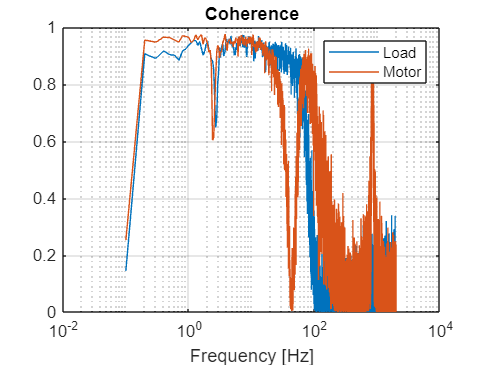

%plotting coherence 
figure()

[coherence_ry, f] = mscohere(d_l,y_l,hann(nfft),n_overlap,nfft,fs);
semilogx(f,abs(coherence_ry))
hold on
[coherence_ry, f] = mscohere(d_m,y_m,hann(nfft),n_overlap,nfft,fs);
semilogx(f,abs(coherence_ry))

title('Coherence')
xlabel('Frequency [Hz]')
legend(legend_names)
grid on; hold off